# Breast Cancer Wisconsin SVM MATLAB Classifier

## Dataset Description

The dataset was obtained for UCI Machine Learning Repisotory the **Breast Cancer Wisconsin (Diagnostic) Data Set** 

This dataset was created to automate breast cancer detection from digitized images of a fine needle aspirate (FNA). It consists of data extracted from a digitized FNA image taken from 569 women whom each was detected with a mass within their breasts. The data has a total of 30 features which describe the characteristics of the cell nuclei present in the image. Each data sample is then placed as either malignant or benign.

More info and the data set can be found here [https://archive.ics.uci.edu/ml/datasets/Breast+Cancer+Wisconsin+%28Diagnostic%29](https://archive.ics.uci.edu/ml/datasets/Breast+Cancer+Wisconsin+%28Diagnostic%29)

The prefix bc_  means breast Cancer

## Step 1: Dataset Preparation

Here we prepare our data so that it can be fed to the svm accordingly. The data is first loaded from an excel xlsx or csv file and the necessry collumns extracted. The data is also shuffled up so as to avoid any variance or bias problems that may arise.

%The prefix bc means breast cancer diagnostic
%Auto detect import options
opts = detectImportOptions('breastCancerFNA.csv');

temp_data = readtable('breastCancerFNA.csv',opts); %Read the csv file and store 
%The readtable function automaticaylly removes any collumn headers from the data if present
data = table2cell(temp_data); %Convert our table to a cell array for ease of access

sample_no = size(data,1) %Get the number of all diagnosis by getting the number of rows

diagnosis_all = 569


%Create our X and Y for SVM Training
rand_num = randperm(sample_no); % Permutate numbers upto the number of samples randomly, This works as shuffling our rows

%Load our X with features
X_temp = cell2mat(data(:,3:32)); %Convert it to a matrix and selecting the collumn ranges containing features
X = X_temp(rand_num(1:end),:); %Store accordingly with the random number permutations

noFeatures = size(X,2); % Store the number of features of the dataset

%Load our Y with our classes.
Y_temp = cell2mat(data(:,2));
%Convert our categorical characters as classnames to indexes
[Y,Classnames] = grp2idx(Y_temp(rand_num(1:end),:));
Classnames %Displays the Classnames labels order: 1 is the first row and so forth

Classnames = 2×1 cell array
    {'B'}
    {'M'}


## Step 2: Perform Cross Validation  : K-fold 10

To reduce any underfitting or overfitting that may occur during testing, the data is cross validated using K-Fold 5 or 10 times. The folds are stratified ensuring a uniform distribution of each class with in each fold further lowering any data bias that would have been present.

%Validate now the training set using Kfold 10 times
%By stratifying we ensure an equal class distribution in all folds
bc_CV = cvpartition(Y,'KFold',10,'Stratify',true);

## Step 3: Feature Ranking

This steps ranks our feature and creates a feature sets consisting  a given number of all the features from 1 feature to all features of the dataset

We use sequential FS to rank the features and store the ranking order in a logical matrix History

opts = statset('display','iter','UseParallel',true); %Sets the display option
rng(5); %This sets our random state.

fun = @(train_data, train_labels, test_data, test_labels)...
    sum(predict(fitcsvm(train_data, train_labels,'Standardize',true,'KernelFunction','linear'), test_data) ~= test_labels);

%Rank our features using Sequential FS forward selection
%Inside history we store the ranking of features
[fs, history] = sequentialfs(fun, X, Y, 'cv', bc_CV, 'options', opts,'nfeatures',noFeatures);

Start forward sequential feature selection:
Initial columns included:  none
Columns that can not be included:  none
Step 1, added column 23, criterion value 0.0843585
Step 2, added column 25, criterion value 0.0439367
Step 3, added column 22, criterion value 0.0281195
Step 4, added column 10, criterion value 0.026362
Step 5, added column 17, criterion value 0.0228471
Step 6, added column 6, criterion value 0.0228471
Step 7, added column 3, criterion value 0.0228471
Step 8, added column 1, criterion value 0.0228471
Step 9, added column 4, criterion value 0.0228471
Step 10, added column 19, criterion value 0.0246046
Step 11, added column 27, criterion value 0.0193322
Step 12, added column 2, criterion value 0.0193322
Step 13, added column 21, criterion value 0.0175747
Step 14, added column 15, criterion value 0.0175747
Step 15, added column 5, criterion value 0.0193322
Step 16, added column 18, criterion value 0.0193322
Step 17, added column 24, criterion value 0.0193322
Step 18, added c

## Step 4: Kernel and Feature Selection

This step now analyzes 4 kernel functions performance in regard to a given feature set

rng(3);
bc_Accuracy(noFeatures,6) = 0; %Initializes where we'll store our performance for each feature set and kernel
for count=1:noFeatures
    %MStore our best features
    bc_Accuracy(count,1) = count;
    
    %Linear
    bc_Model= fitcsvm(X(:,history.In(count,:)),Y,'BoxConstraint',1,'CVPartition',bc_CV,'KernelFunction',...
        'linear','Standardize',true,'KernelScale','auto');
    %This averages our cross validated models loss. The lower the better the prediction
    % Compute validation accuracy
    bc_Accuracy(count,2) = (1 - kfoldLoss(bc_Model, 'LossFun', 'ClassifError'))*100;
    
    %rbf training
    bc_Model= fitcsvm(X(:,history.In(count,:)),Y,'BoxConstraint',1,'CVPartition',bc_CV,'KernelFunction',...
        'rbf','Standardize',true,'KernelScale','auto');
    %This averages our cross validated models loss. The lower the better the prediction
    % Compute validation accuracy
    bc_Accuracy(count,3) = (1 - kfoldLoss(bc_Model, 'LossFun', 'ClassifError'))*100;
    
    %Gaussian
    bc_Model= fitcsvm(X(:,history.In(count,:)),Y,'BoxConstraint',1,'CVPartition',bc_CV,'KernelFunction',...
        'gaussian','Standardize',true,'KernelScale','auto');
    %This averages our cross validated models loss. The lower the better the prediction
    % Compute validation accuracy
    bc_Accuracy(count,4) = (1 - kfoldLoss(bc_Model, 'LossFun', 'ClassifError'))*100;
    
    %Polynomial
    bc_Model= fitcsvm(X(:,history.In(count,:)),Y,'BoxConstraint',1,'CVPartition',bc_CV,'KernelFunction',...
        'polynomial','Standardize',true,'KernelScale','auto');
    %This averages our cross validated models loss. The lower the better the prediction
    % Compute validation accuracy
    bc_Accuracy(count,5) = (1 - kfoldLoss(bc_Model, 'LossFun', 'ClassifError'))*100;
    
    %Polynomial power 3
    bc_Model= fitcsvm(X(:,history.In(count,:)),Y,'BoxConstraint',1,'CVPartition',bc_CV,'KernelFunction',...
        'polynomial','Standardize',true,'KernelScale','auto','PolynomialOrder',3);
    %This averages our cross validated models loss. The lower the better the prediction
    % Compute validation accuracy
    bc_Accuracy(count,6) = (1 - kfoldLoss(bc_Model, 'LossFun', 'ClassifError'))*100;
end

## Visualize Results

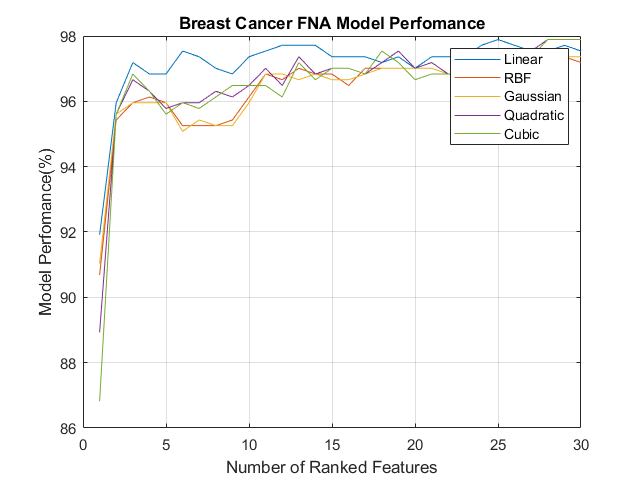

figure
plot(bc_Accuracy(:,2:6))
title('Breast Cancer FNA Model Perfomance')
xlabel('Number of Ranked Features')
ylabel('Model Perfomance(%)')
legend('Linear','RBF','Gaussian','Quadratic','Cubic')
grid on;

## Step 5: Model Selection: Best Hyperparameters

We now need to search for the best hyperparameters for the highest accuracy perfomance for the dataset.The following functions will be utilized to tune the SVM parameters C and Kernel function variables We use fitcsvm and train using the best features obtained from step 4. The kernel function is selected from the best perfoming Kernel in the previous step

%The best observed Kernel is the polynomial of an order of 3
%For the bayesain optimizer we let it use the defaults but increase its Maximum Objective evaluations to 80
bc_Model = fitcsvm(X(:,history.In(30,:)),Y,'KernelFunction','polynomial','cost',cost,'Standardize',true,...
    'OptimizeHyperparameters','auto', 'HyperparameterOptimizationOptions',struct('UseParallel',true,...
    'ShowPlots',false,'MaxObjectiveEvaluations',30,'Repartition',true));

Copying objective function to workers...
Done copying objective function to workers.
|===============================================================================================================|
| Iter | Active  | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | BoxConstrain-|  KernelScale |
|      | workers | result |             | runtime     | (observed)  | (estim.)    | t            |              |
|===============================================================================================================|
|    1 |       2 | Best   |     0.45711 |     0.23838 |     0.45711 |     0.45711 |      0.32666 |        813.1 |
|    2 |       2 | Error  |         NaN |      0.1406 |         NaN |     0.45711 |    0.0023879 |    0.0034008 |
|    3 |       2 | Accept |     0.45711 |     0.63339 |     0.45711 |     0.45711 |       0.3529 |       256.64 |
|    4 |       2 | Accept |     0.45711 |     0.19764 |     0.45711 |     0.45711 |     0.077064 |       940.72 |
|  

## Step 6: Train a SVM and Evaluate Validation Loss : Kernel Polynomial

This step will now train the SVM using a polynomial kernel SVM first.

%Pass on our X and Y to the SVM classifier.
%rng(3); %seeds our random generator allowing for reproducibility of results
%Box Costraint is our penalty factor C, the higher the stricter the hyperplane
constraint = bc_Model.BoxConstraints(1,:);
kernelScale = bc_Model.KernelParameters.Scale;
%To lower our false negative rate we introduce a cost parameter
% to increase the cost of misclassifying Malignant as Benign
cost.ClassNames = {'2' '1'};
cost.ClassificationCosts = [0 2;1 0];

%using a polynomial kernel
best_bc_Model = fitcsvm(X(:,history.In(30,:)),Y,'CVPartition',bc_CV,'KernelFunction',...
    'polynomial','Standardize',true,'BoxConstraint',1,'KernelScale',5.5,'Cost',cost);

%This averages our cross validated models loss. The lower the better the prediction
% Compute validation accuracy
validationAccuracy = (1 - kfoldLoss(best_bc_Model, 'LossFun', 'ClassifError'))*100

validationAccuracy = 97.1831

%This averages our cross validated models loss. The lower the better the prediction
bc_ModelLoss = kfoldLoss(best_bc_Model)

bc_ModelLoss = 0.0282

## Step 7: Evaluate the model's perfomance using a confusion Matrix

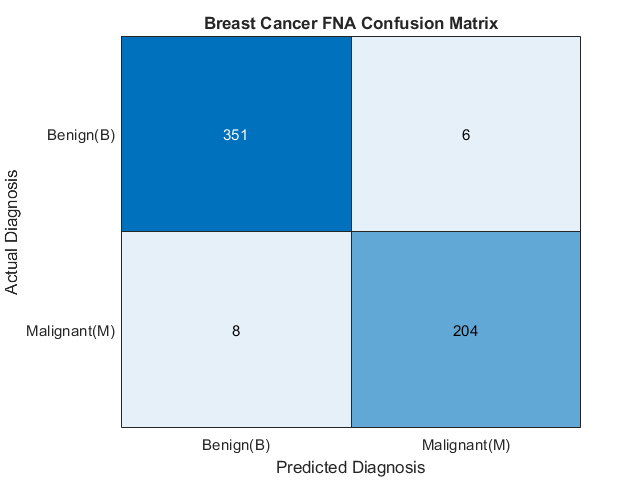

[Y_pred, validationScores] = kfoldPredict(best_bc_Model);
conMat=confusionmat(Y,Y_pred);
%Generate a Confusion Matrix
%The confusion matrix gives us a view of the rate of true positives to false negatives.
%It enables to have proper view of how effecive our model is in prediction of illness minimizing of having false negatives
conMatHeat = heatmap(conMat,'Title','Breast Cancer FNA Confusion Matrix','YLabel','Actual Diagnosis','XLabel','Predicted Diagnosis',...
    'XDisplayLabels',{'Benign(B)','Malignant(M)'},'YDisplayLabels',{'Benign(B)','Malignant(M)'},'ColorbarVisible','off');

%The following functions compute the precision and F1 Score
precisionFunc = @(confusionMat) diag(confusionMat)./sum(confusionMat,2);
recallFunc = @(confusionMat) diag(confusionMat)./sum(confusionMat,1);
f1ScoresFunc = @(confusionMat) 2*(precisionFunc(confusionMat).*recallFunc(confusionMat))./(precisionFunc(confusionMat)+recallFunc(confusionMat));
meanF1Func = @(confusionMat) mean(f1ScoresFunc(confusionMat));

falseNegativeRate = (conMat(2,1)/(conMat(2,1)+conMat(2,2)))*100

falseNegativeRate = 3.7736


precision = precisionFunc(conMat)

precision =     0.9832
    0.9623


recall = recallFunc(conMat)

recall =     0.9777    1.6714
    0.5682    0.9714


f1Score = meanF1Func(conMat)

f1Score =     0.8475    1.1025
